# HRA of TF-IDF-rank signal

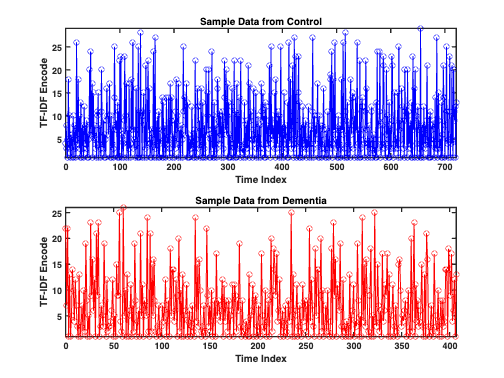

clc
clearvars
close all

data_dir1 = fullfile(pwd,"data/hra/tf-idf_control/");
data_dir2 = fullfile(pwd,"data/hra/tf-idf_dementia/");

fnames_hc = dir(data_dir1);
fnames_hc = fnames_hc(~ismember({fnames_hc.name},{'.','..'}));
fnames_ad = dir(data_dir2);
fnames_ad = fnames_ad(~ismember({fnames_ad.name},{'.','..'}));

x1 = readtable(fullfile(data_dir1,fnames_hc(1).name));
x2 = readtable(fullfile(data_dir2,fnames_ad(1).name));

subplot(2,1,1)
plot(x1.index,x1.x,'-o','Color','blue')
axis tight
title("Sample Data from Control")
xlabel("Time Index")
ylabel("TF-IDF Encode")
set(gca,'FontWeight','bold','LineWidth',1.5)

subplot(2,1,2)
plot(x2.index,x2.x,'-o','Color','red')
axis tight
title("Sample Data from Dementia")
xlabel("Time Index")
ylabel("TF-IDF Encode")
set(gca,'FontWeight','bold','LineWidth',1.5)

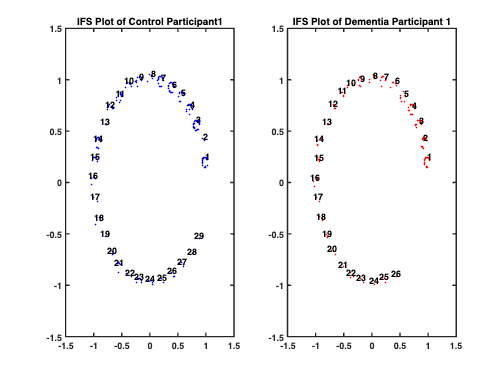

num_id = 32;
alpha = 0.05;

sig1 = x1.x;
ifs_hc = IFS(sig1,num_id,alpha);
sig2 = x2.x;
ifs_ad = IFS(sig2,num_id,alpha);
ifs_hc(1,:) = [];
ifs_ad(1,:) = [];

subplot(1,2,1)
plot(ifs_hc(:,1),ifs_hc(:,2),'.','Color','b')
for i=1:num_id
    id_idx = find(sig1 == i);
    c = mean(ifs_hc(id_idx,:),1);
    text(c(1)+0.08,c(2)+0.08,num2str(i),'FontWeight','bold',...
        'VerticalAlignment','top','HorizontalAlignment','right')
end
ylim([-1.5,1.5])
xlim([-1.5,1.5])
title('IFS Plot of Control Participant1')
set(gca,'LineWidth',1.5,'FontWeight','bold')
subplot(1,2,2)
plot(ifs_ad(:,1),ifs_ad(:,2),'.','Color','r')
for i=1:num_id
    id_idx = find(sig2 == i);
    c = mean(ifs_ad(id_idx,:),1);
    text(c(1)+0.08,c(2)+0.08,num2str(i),'FontWeight','bold',...
        'VerticalAlignment','top','HorizontalAlignment','right')
end
ylim([-1.5,1.5])
xlim([-1.5,1.5])
title('IFS Plot of Dementia Participant 1')
set(gca,'LineWidth',1.5,'FontWeight','bold')

fsize1 = size(fnames_hc,1);
fsize2 = size(fnames_ad,1);

feat_mx = NaN(fsize1+fsize2,num_id*3+num_id^2*3);
alpha = 0.04;

for i=1:fsize1
%     if mod(i,10) == 0
%         out = sprintf("HC File [%i/%i]", i, fsize2);
%         disp(out);
%     end
    
    csig = readtable(fullfile(data_dir1,fnames_hc(i).name));
    csig = csig.x + 1;
    ifs_add = IFS(csig,num_id,alpha);
    
    feat_vec1 = heterorecurrence(ifs_add,csig,num_id);
    feat_vec2 = heterorecurrence2(ifs_add,csig,num_id);
    feat_mx(i,:) = [feat_vec1, feat_vec2];
end

for i=1:fsize2
%     if mod(i,10) == 0
%         out = sprintf("AD File [%i/%i]", i, fsize2);
%         disp(out)
%     end

    csig = readtable(fullfile(data_dir2,fnames_ad(i).name));
    csig = csig.x + 1;
    ifs_add = IFS(csig,num_id,alpha);

    feat_vec1 = heterorecurrence(ifs_add,csig,num_id);
    feat_vec2 = heterorecurrence2(ifs_add,csig,num_id);
    feat_mx(fsize1+i,:) = [feat_vec1, feat_vec2];
end

# HRA of dictionary order signal

clc
clearvars
close all

data_dir1 = fullfile(pwd,"data/hra/control/");
data_dir2 = fullfile(pwd,"data/hra/dementia/");

fnames_hc = dir(data_dir1);
fnames_hc = fnames_hc(~ismember({fnames_hc.name},{'.','..'}));
fnames_ad = dir(data_dir2);
fnames_ad = fnames_ad(~ismember({fnames_ad.name},{'.','..'}));

num_id = 32;

## Plot sample data

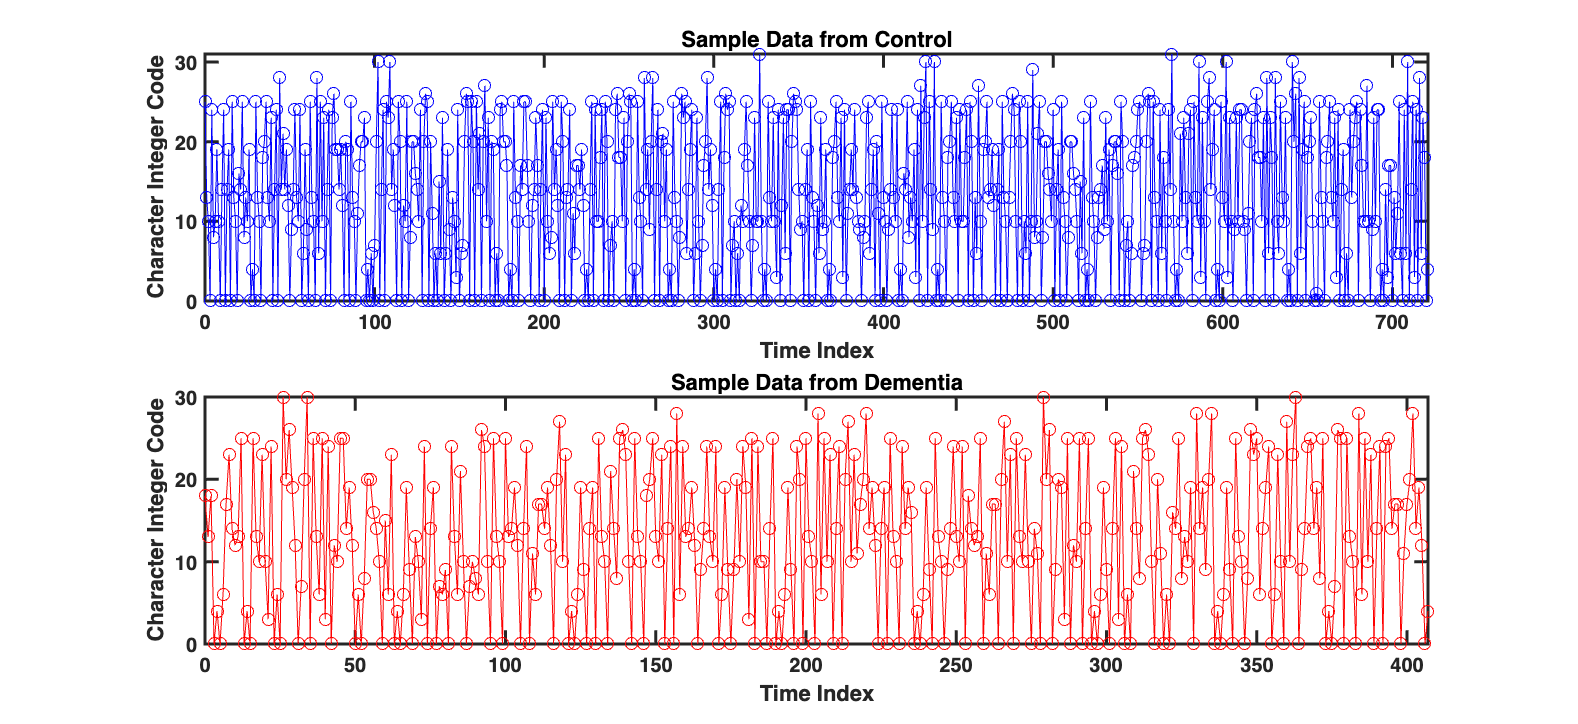

x1 = readtable(fullfile(data_dir1,fnames_hc(1).name));
x2 = readtable(fullfile(data_dir2,fnames_ad(1).name));

figure('Color','w','Position',[100,100,1200,550])
subplot(2,1,1)
plot(x1.index,x1.x,'-o','Color','blue')
axis tight
title("Sample Data from Control")
xlabel("Time Index")
ylabel("Character Integer Code")
set(gca,'FontWeight','bold','LineWidth',1.5)

subplot(2,1,2)
plot(x2.index,x2.x,'-o','Color','red')
axis tight
title("Sample Data from Dementia")
xlabel("Time Index")
ylabel("Character Integer Code")
set(gca,'FontWeight','bold','LineWidth',1.5)

for i=0:(num_id-1)
    id_idx = find(x1.x == i);
    s = sprintf('ID %i: %i', i+1, length(id_idx));
    disp(s)
end

ID 1: 150
ID 2: 1
ID 3: 0
ID 4: 9
ID 5: 17
ID 6: 0
ID 7: 31
ID 8: 8
ID 9: 11
ID 10: 13
ID 11: 80
ID 12: 7
ID 13: 12
ID 14: 38
ID 15: 44
ID 16: 2
ID 17: 6
ID 18: 15
ID 19: 16
ID 20: 32
ID 21: 44
ID 22: 6
ID 23: 0
ID 24: 35
ID 25: 46
ID 26: 62
ID 27: 12
ID 28: 4
ID 29: 10
ID 30: 1
ID 31: 8
ID 32: 2


for i=0:(num_id-1)
    id_idx = find(x2.x == i);
    s = sprintf('ID %i: %i', i+1, length(id_idx));
    disp(s)
end

ID 1: 85
ID 2: 0
ID 3: 0
ID 4: 6
ID 5: 10
ID 6: 0
ID 7: 24
ID 8: 4
ID 9: 7
ID 10: 14
ID 11: 35
ID 12: 6
ID 13: 11
ID 14: 22
ID 15: 31
ID 16: 1
ID 17: 3
ID 18: 9
ID 19: 4
ID 20: 24
ID 21: 16
ID 22: 3
ID 23: 0
ID 24: 15
ID 25: 22
ID 26: 34
ID 27: 7
ID 28: 4
ID 29: 7
ID 30: 0
ID 31: 4
ID 32: 0


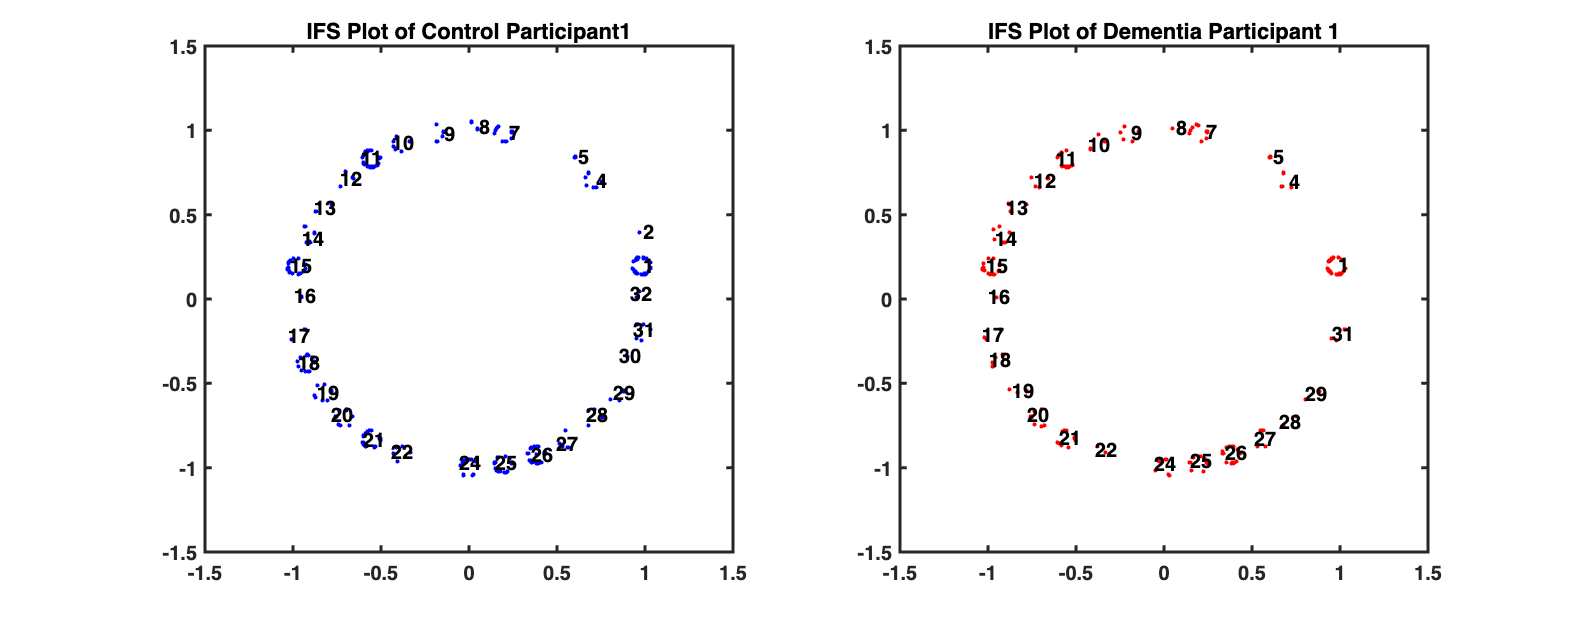

alpha = 0.05;
sig1 = x1.x + 1;
ifs_hc = IFS(sig1,num_id,alpha);
sig2 = x2.x + 1;
ifs_ad = IFS(sig2,num_id,alpha);
ifs_hc(1,:) = [];
ifs_ad(1,:) = [];

figure('Color','w','Position',[0,0,1400,550]);
subplot(1,2,1)
plot(ifs_hc(:,1),ifs_hc(:,2),'.','Color','b')
for i=1:num_id
    id_idx = find(sig1 == i);
    c = mean(ifs_hc(id_idx,:),1);
    text(c(1)+0.08,c(2)+0.08,num2str(i),'FontWeight','bold',...
        'VerticalAlignment','top','HorizontalAlignment','right')
end
title('IFS Plot of Control Participant1')
set(gca,'LineWidth',1.5,'FontWeight','bold')
subplot(1,2,2)
plot(ifs_ad(:,1),ifs_ad(:,2),'.','Color','r')
for i=1:num_id
    id_idx = find(sig2 == i);
    c = mean(ifs_ad(id_idx,:),1);
    text(c(1)+0.08,c(2)+0.08,num2str(i),'FontWeight','bold',...
        'VerticalAlignment','top','HorizontalAlignment','right')
end
title('IFS Plot of Dementia Participant 1')
set(gca,'LineWidth',1.5,'FontWeight','bold')

## Quantifications of IFS patterns

fsize1 = size(fnames_hc,1);
fsize2 = size(fnames_ad,1);
feat_mx = NaN(fsize1+fsize2,32*3+32*32*3);

alpha = 0.04;
nbins = 0;

for i=1:fsize1
%     out = sprintf("HC File [%i/%i]", i, fsize2);
%     disp(out);
    
    csig = readtable(fullfile(data_dir1,fnames_hc(i).name));
    csig = csig.x + 1;
    ifs_add = IFS(csig,num_id,alpha);
    
    % 1st order
    for j=1:num_id
        [feat_mx(i,j),feat_mx(i,j+num_id),feat_mx(i,j+num_id*2)] = ...
            heterorecurrence(ifs_add,csig,j,nbins);
        % 2nd order
        for k=1:num_id
            [feat_mx(i,k+96*j),feat_mx(i,k+96*j+num_id),feat_mx(i,k+96*j+num_id*2)] = ...
                heterorecurrence2(ifs_add,csig,j,k);
        end
    end
end

for i=1:fsize2
%     out = sprintf("AD File [%i/%i]", i, fsize2);
%     disp(out)

    csig = readtable(fullfile(data_dir2,fnames_ad(i).name));
    csig = csig.x + 1;
    ifs_add = IFS(csig,num_id,alpha);

    % 1st order
    for j=1:num_id
        [feat_mx(fsize1+i,j),feat_mx(fsize1+i,j+num_id),feat_mx(fsize1+i,j+num_id*2)] = ...
            heterorecurrence(ifs_add,csig,j,nbins);
        % 2nd order
        for k=1:num_id
            [feat_mx(fsize1+i,k+96*j),feat_mx(fsize1+i,k+96*j+num_id),feat_mx(fsize1+i,k+96*j+num_id*2)] = ...
                heterorecurrence2(ifs_add,csig,j,k);
        end
    end
end

# Variable screening (PCA/KS Test)

clc
close all
clearvars

load(fullfile(pwd,"data","hra","tfidf_hrq_mx2.mat"))
num_id = 32;

## PCA without removing zero columns

w = 1./(var(feat_mx)+eps);
[~,score,~,~,explained] = pca(feat_mx,'VariableWeights',w);

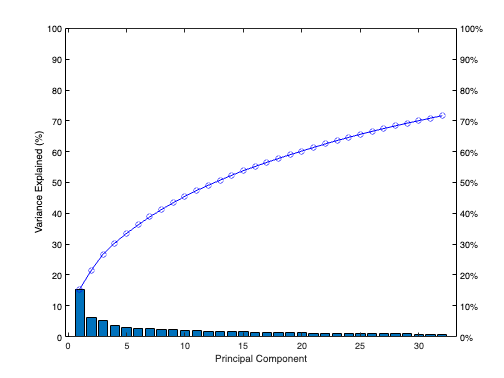

percent_ticks = string(0:10:100);
for i=1:length(percent_ticks)
    percent_ticks(i) = strcat(percent_ticks(i),"%");
end

figure
yyaxis left
bar(explained(1:num_id))
ylim([0,100])
set(get(gca,'YLabel'), 'String','Variance Explained (%)')
set(gca, 'YColor','black')
yyaxis right
plot(1:num_id,cumsum(explained(1:num_id)),'o-','Color','blue')
ylim([0,100])
yticklabels(percent_ticks)
set(gca, 'YColor','black')
xlabel('Principal Component')

## Remove zeros columns and perform the KS test

zidx = all(feat_mx==0,1);
feat_mx(:,zidx) = [];
num_hc = 243;

out_mx = NaN(size(feat_mx,2),4);
out_mx(:,4) = find(~zidx)';
for i=1:size(feat_mx,2)
    [out_mx(i,1),out_mx(i,2),out_mx(i,3)] = kstest2(feat_mx(1:num_hc,i),feat_mx(num_hc+1:end,i), ...
        'Alpha',0.05,'Tail','unequal');
end

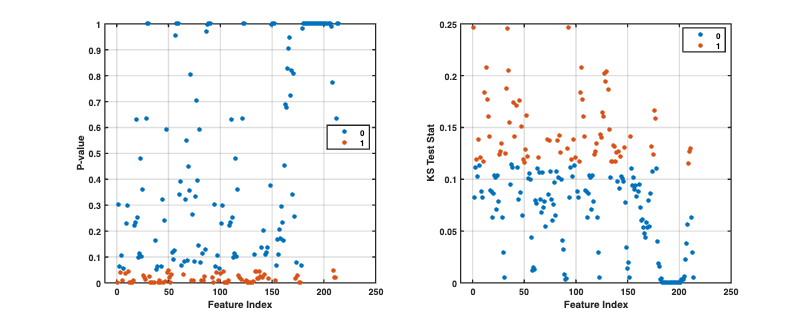

g = categorical(out_mx(:,1));
cidx = 1:size(feat_mx,2);

f = figure('Color','w','Position',[0,0,980,385]);
subplot(1,2,1)
gscatter(cidx,out_mx(:,2),g)
grid on
xlabel("Feature Index")
ylabel("P-value")
set(gca,'FontWeight','bold','LineWidth',1.5)

subplot(1,2,2)
gscatter(cidx,out_mx(:,3),g)
grid on
xlabel("Feature Index")
ylabel("KS Test Stat")
set(gca,'FontWeight','bold','LineWidth',1.5)

disp(out_mx(out_mx(:,3)>0.2,4)')

     1    13    34    35    93   105   128   130



## Visualization of the distributional differneces of features

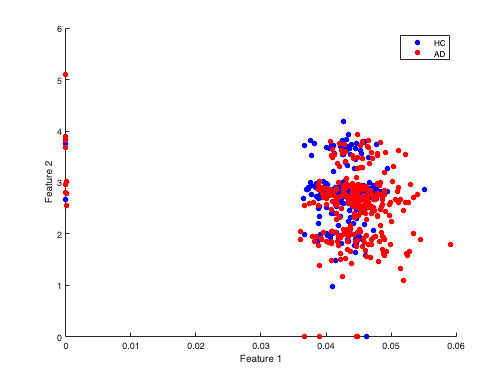

[~,max_idx] = maxk(out_mx(:,3),5);
i1 = max_idx(1);
i2 = max_idx(3);
figure('Color','w')
scatter(feat_mx(1:num_hc,i1),feat_mx(1:num_hc,i2),'filled','MarkerFaceColor','b')
hold on
scatter(feat_mx((num_hc+1):end,i1),feat_mx((num_hc+1):end,i2),'filled','MarkerFaceColor','r')
hold off
xlabel("Feature 1")
ylabel("Feature 2")
legend(["HC","AD"])

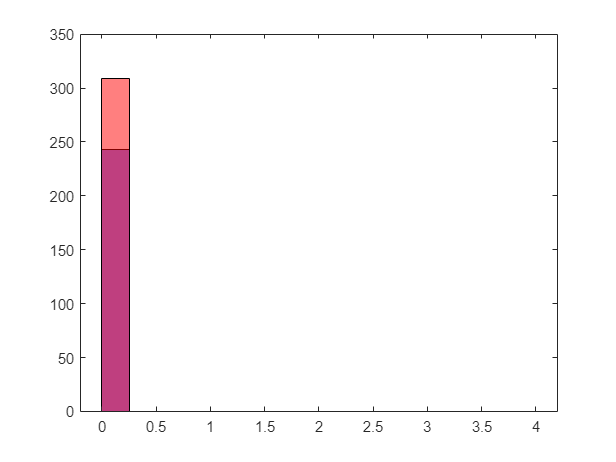

histogram(feat_mx(1:num_hc,i1),0:0.25:4,'FaceColor','b','FaceAlpha',0.5)
hold on
histogram(feat_mx(num_hc+1:end,i1),0:0.25:4,'FaceColor','r','FaceAlpha',0.5)
hold off

train classifiers

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Lambda |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.41403 |     0.26877 |     0.41403 |     0.41403 |       26.328 |
|    2 | Accept |     0.44344 |      6.1006 |     0.41403 |     0.41593 |    0.0003516 |
|    3 | Accept |     0.42308 |     0.87026 |     0.41403 |     0.41403 |      0.27286 |
|    4 | Accept |     0.45701 |      5.1519 |     0.41403 |     0.41403 |   5.6752e-08 |
|    5 | Accept |     0.43439 |       0.112 |     0.41403 |     0.42552 |       225.71 |
|    6 | Best   |     0.40498 |     0.36545 |     0.40498 |     0.40498 |       3.9664 |
|    7 | Accept |     0.41629 |     0.29451 |     0.40498 |     0.41239 |       5.9488 |
|    8 | Accept |    

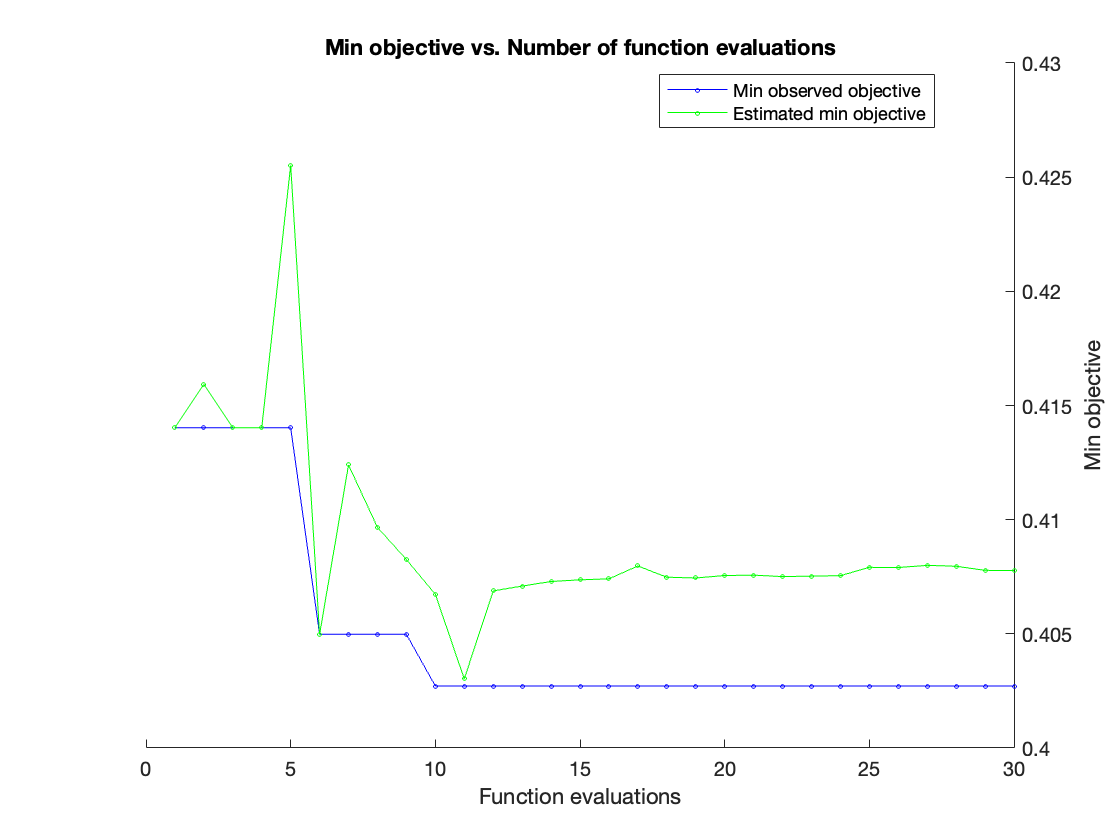

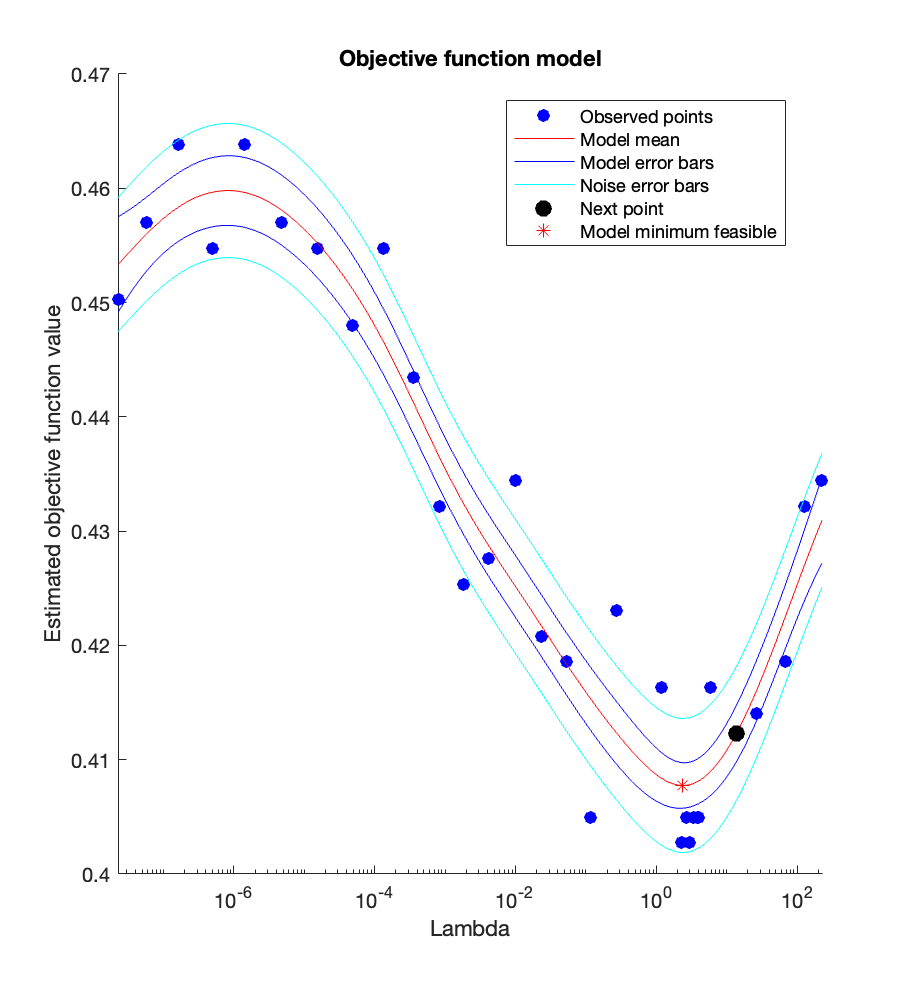


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 92.3253 seconds
Total objective function evaluation time: 82.0959

Best observed feasible point:
    Lambda
    ______

    2.9555

Observed objective function value = 0.40271
Estimated objective function value = 0.40781
Function evaluation time = 0.35706

Best estimated feasible point (according to models):
    Lambda
    ______

    2.7006

Estimated objective function value = 0.40777
Estimated function evaluation time = 0.39302



% feat_mx2 = feat_mx(:,out_mx(:,3) > quantile(out_mx(:,3),0.9));
feat_mx2 = feat_mx;
ybool = zeros(size(feat_mx2,1),1);
ybool(num_hc+1:end) = 1;
ybool = logical(ybool);

test_ratio = 0.2;
cv = cvpartition(ybool,'Holdout',test_ratio);
trn_idx = training(cv);
eval_idx = test(cv);

[mdl,fit_info] = fitclinear(feat_mx2(trn_idx,:)',ybool(trn_idx),'ObservationsIn','columns',...
    'Learner','logistic',...
    'OptimizeHyperparameters',{'Lambda'},'HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus'));

yhat = predict(mdl,feat_mx2(eval_idx,:));
c = confusionmat(ybool(eval_idx),yhat);
disp(c)

    10    39
    12    49



statsOfMeasure(c,1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"          10         49       29.5        29.5 
    "false_positive"         12         39       25.5        25.5 
    "false_negative"         39         12       25.5        25.5 
    "true_negative"          49         10       29.5        29.5 
    "precision"         0.45455    0.55682    0.50568     0.53636 
    "sensitivity"       0.20408    0.80328    0.50368     0.53636 
    "specificity"       0.80328    0.20408    0.50368     0.53636 
    "accuracy"          0.53636    0.53636    0.53636     0.53636 
    "F-measure"         0.28169    0.65772     0.4697     0.53636 


## PCA Transformation

w = 1./(var(feat_mx2)+eps);
[~,score,~,~,explained] = pca(feat_mx2,'VariableWeights',w);

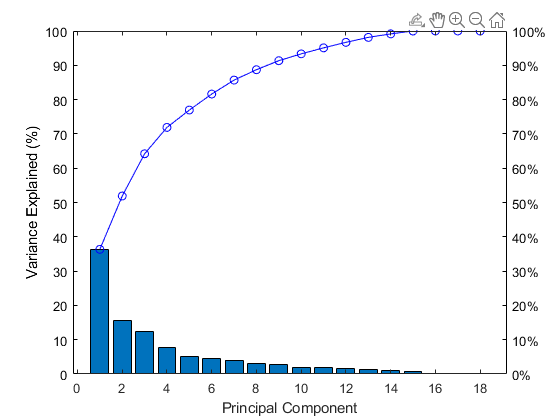

percent_ticks = string(0:10:100);
for i=1:length(percent_ticks)
    percent_ticks(i) = strcat(percent_ticks(i),"%");
end

figure('Color','w')
yyaxis left
bar(explained(1:end))
ylim([0,100])
set(get(gca,'YLabel'), 'String','Variance Explained (%)')
set(gca, 'YColor','black')
yyaxis right
plot(1:18,cumsum(explained(1:end)),'o-','Color','blue')
ylim([0,100])
yticklabels(percent_ticks)
set(gca, 'YColor','black')
xlabel('Principal Component')

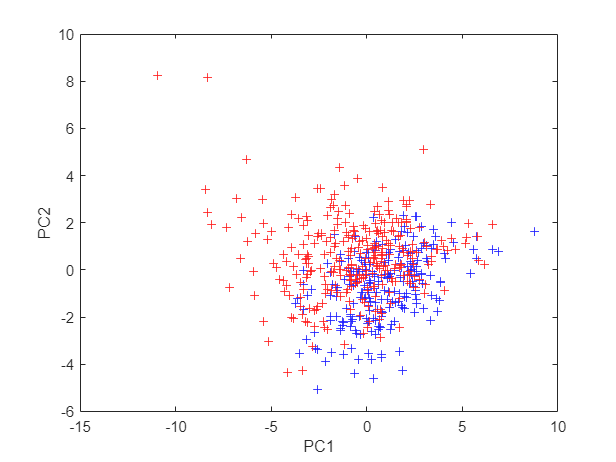

figure('Color','w')
plot(score(1:num_hc,1),score(1:num_hc,2),'+','Color','b')
hold on
plot(score(num_hc+1:end,1),score(num_hc+1:end,2),'+','Color','r')
hold off
xlabel("PC1")
ylabel("PC2")

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Lambda |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.29186 |    0.077466 |     0.29186 |     0.29186 |   0.00010434 |
|    2 | Accept |     0.43891 |    0.062048 |     0.29186 |     0.30092 |       25.954 |
|    3 | Accept |     0.29186 |    0.051398 |     0.29186 |     0.29186 |   1.6058e-06 |
|    4 | Best   |     0.28959 |    0.048402 |     0.28959 |     0.28961 |     0.008247 |
|    5 | Accept |     0.29186 |    0.050903 |     0.28959 |     0.28961 |   2.2682e-08 |
|    6 | Accept |     0.28959 |    0.051732 |     0.28959 |     0.28952 |    0.0014074 |
|    7 | Accept |     0.29186 |     0.05184 |     0.28959 |      0.2895 |   1.5022e-07 |
|    8 | Accept |    

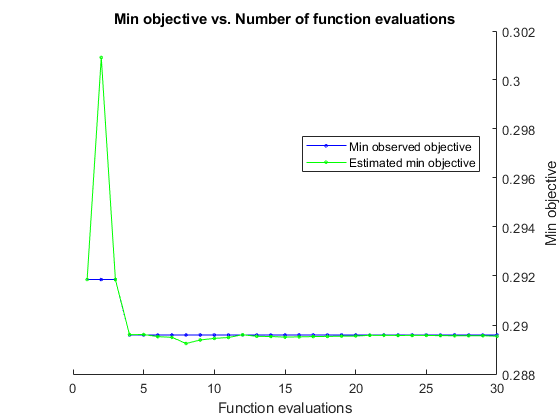

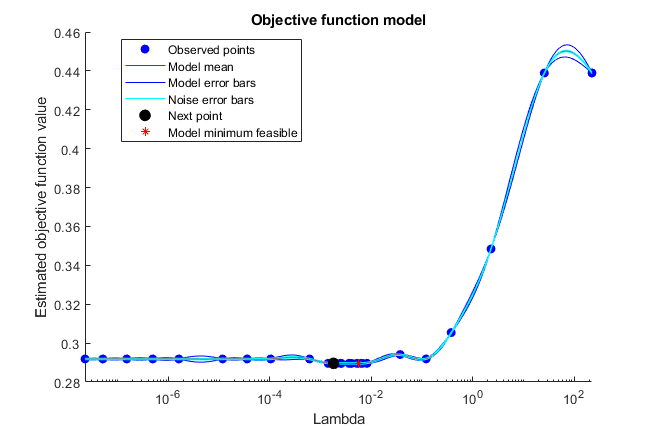


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 9.5177 seconds
Total objective function evaluation time: 1.5957

Best observed feasible point:
     Lambda 
    ________

    0.008247

Observed objective function value = 0.28959
Estimated objective function value = 0.28981
Function evaluation time = 0.048402

Best estimated feasible point (according to models):
     Lambda 
    ________

    0.005243

Estimated objective function value = 0.28954
Estimated function evaluation time = 0.05298



pc_idx = 8;
test_ratio = 0.2;
cv = cvpartition(ybool,'Holdout',test_ratio);
trn_idx = training(cv);
eval_idx = test(cv);

[mdl,fit_info] = fitclinear(score(trn_idx,1:pc_idx)',ybool(trn_idx),'ObservationsIn','columns',...
    'Learner','logistic',...
    'OptimizeHyperparameters',{'Lambda'},'HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus'));

hat = predict(mdl,score(eval_idx,1:pc_idx));
c = confusionmat(ybool(eval_idx),yhat);
disp(c)

    28    21
    10    51



statsOfMeasure(c,1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"          28         51       39.5        39.5 
    "false_positive"         10         21       15.5        15.5 
    "false_negative"         21         10       15.5        15.5 
    "true_negative"          51         28       39.5        39.5 
    "precision"         0.73684    0.70833    0.72259     0.71818 
    "sensitivity"       0.57143    0.83607    0.70375     0.71818 
    "specificity"       0.83607    0.57143    0.70375     0.71818 
    "accuracy"          0.71818    0.71818    0.71818     0.71818 
    "F-measure"         0.64368    0.76692     0.7053     0.71818 
